# View Activations from GoogLeNet

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads GoogLeNet and displays its layers.

net = googlenet;
net.Layers

ans =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution              

## Task 1

GoogLeNet was trained to classify natural images like animals and plants. It should be able to find interesting features from a photograph of some violets.

flwrImage = imread("../data/violet.jpg");

## Task 2

You can extract features from an input image using a CNN with the `activations` function.

This function accepts three inputs: the network, the input image, and the layer to extract features from

`features` `=` `activations``(``net``,``img``,``layer``)`

The first convolution layer in GoogLeNet is named `"conv1-7x7_s2"`. You can see this by viewing the network's layers.

actvn = activations(net, flwrImage, "conv1-7x7_s2");

## Task 3

Each convolution layer consists of many 2-D arrays called *channels*. The `"conv1-7x7_s2"` layer has 64 channels, so it is difficult to inspect all channels at once.

The provided function `showActivationsForChannel` will display the activations from a specific channel. It is located at the bottom of the script. Use the image, the features, and the desired channel number as input.

A white pixel indicates that the channel is positively activated at that position. A black pixel is where the channel activated negatively.

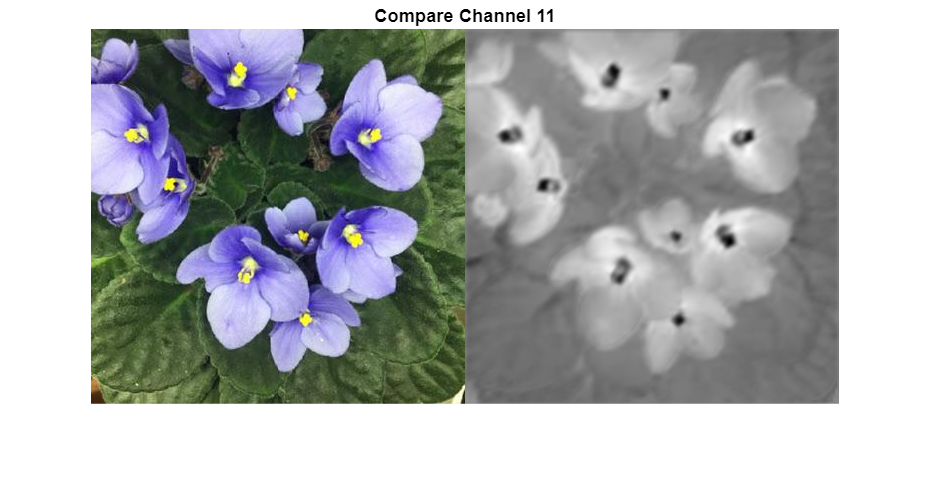

showActivationsForChannel(flwrImage, actvn, 11)

## Task 4

Channel 11 activates on colors with high blue values, such as violet. Channel 4 activates on edges from light to dark.

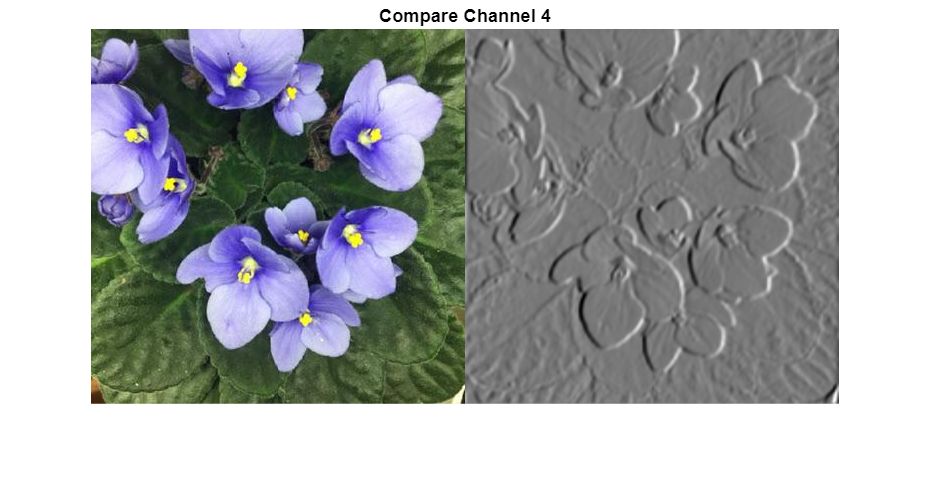

showActivationsForChannel(flwrImage, actvn, 4)

## Task 5

Most CNNs learn to detect features like color and edges in the first convolution layer. In deeper layers, the network learns more complicated features.

actvn5 = activations(net, flwrImage, "inception_5b-output");

## Task 6

The `"inception_5b-output"` layer contains 1024 channels.

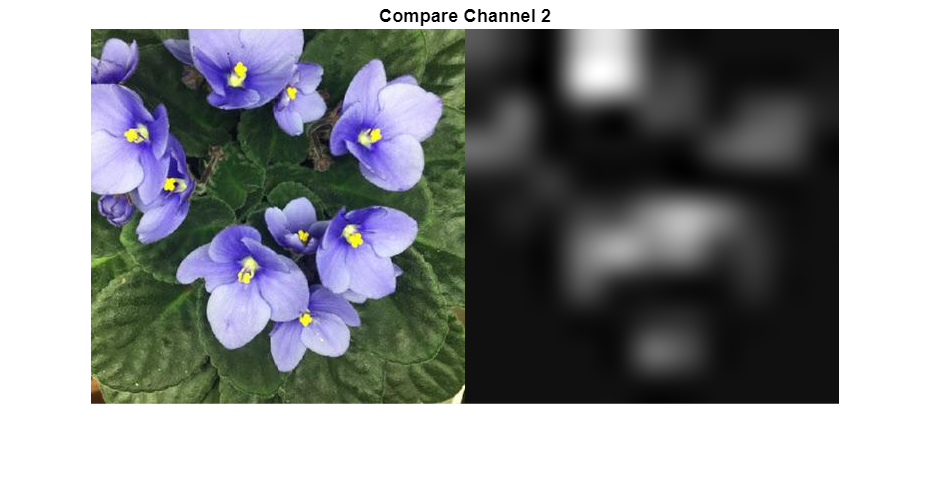

showActivationsForChannel(flwrImage, actvn5, 2)

This function displays the original image and the activations for one channel.

function showActivationsForChannel(origImage, ac, ch)
    imageSize = size(origImage);
    imageSize = imageSize([1 2]);
    
    act_ch = ac(:, :, ch);
    act_ch = imresize(mat2gray(act_ch), imageSize);
    imshowpair(origImage, act_ch, "montage")
    title(['Compare Channel ', num2str(ch)])
end